density = @(p) double_stunted_gaussian(p,1/2,1/10);
gamma = @(p) double_stunted_gaussian_gamma(p,1/2,1/10);
tolerance = 5; % In terms of Basis Points

moneyline_struct = moneyline_solver(density,gamma,tolerance);

if moneyline_struct.matched_answers
    real_profit = moneyline_struct.profit_numerical
else
    profit_numerical = moneyline_struct.profit_numerical
    profit_newton = moneyline_struct.profit_newton
end

real_profit = 0.0595

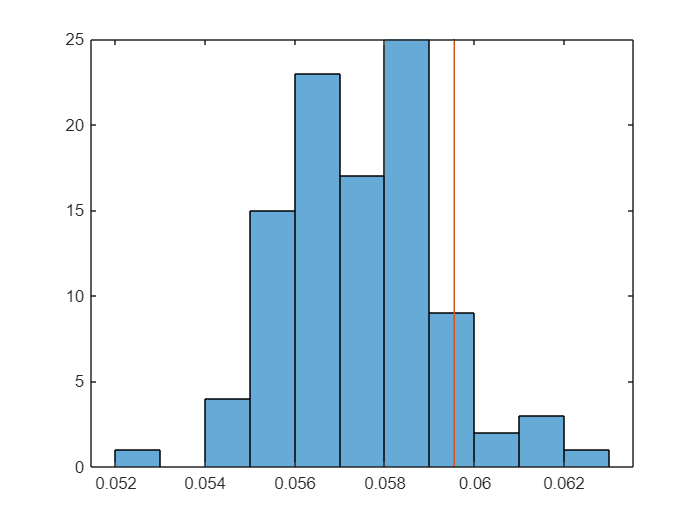


num_trials = 100;
trial_profits = nan(1,num_trials);
for trial_index = 1:num_trials
    sample_values = distribution_sample(density,1e3);
    trial_profits(trial_index) = classical_profit_from_sample(sample_values,tolerance);
end

h = histogram(trial_profits);
hold on
plot(real_profit*ones(1,2),[0 max(h.BinCounts)])